# SimplePendulumExplorer

Calculates motion of a nonlinear pendulum and simulates laboratory measurements and analysis.

Author: Duncan Carlsmith 

## Introduction

A common laboratory exercise in introductory physics entails observation of the motion of a simple pendulum using a [photogate](https://www.pasco.com/products/guides/photogates) stationed at the stable equilibrium point. The student measures the period as a function of maximum angular displacement and attempts to examine the validity of the harmonic small angle approximation.  

This Live Script calculates the exact solution for the motion of an ideal nonlinear pendulum released from rest for a range of initial angles and compares the results to those obtained by numerical integration of the equation of motion and to the harmonic approximation. It illustrates nonlinear fitting of simulated student data for period versus amplitude with exact and approximate models.  The script may interest students and instructors of physics and engineering. Try this suggestions are included for further exploration.

The angle $\theta(t)$ of an ideal simple pendulum of length $L$ subject to gravitational acceleration $g$ is governed by the equation $\ddot\theta = -\omega_0^2\sin\theta$ with $\omega_0=\sqrt{g/L}$ the natural frequency. This equation is most readily derived by equating the rate of change of angular momentum about the support point to the torque about the support point: $I\ddot\theta=N= -LMg\sin\theta$ where $M$ is the mass and $I=ML^2$ the moment of inertia. 

For small angles, $\sin\theta\simeq\theta$ and the general solution is harmonic: $\theta(t)=\theta_0\cos(\omega_0t+\phi_0)$ and the period is independent of amplitude. For large angles, the general solution is expressible in terms of elliptic integrals and the solution starting from rest at angle $\theta_0$ is [1]


$$\theta(t)=2\sin^{-1}[\sin{\theta_0\over 2}{\rm cd}(\omega_0t,\sin^2{\theta_0\over 2})]$$


where ${\rm cd}(u,m)\equiv {\rm cn}(u,m)/{\rm dn}(u,m)$ and the [Jacobi elliptic functions](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions) are defined (in MATLAB) by 


$$u=\int_0^\phi{d\theta\over\sqrt{1-m\sin^2\theta}}$$


with ${\rm sn}(u)=\sin\phi$, ${\rm cn}(u)=\cos\phi$, and ${\rm dn}(u)=\sqrt{1-m\sin^2\phi}$ with ${\rm sn}^2+{\rm cn}^2=1$. (Note that Ref [1] replaces $m$ with $m^2$ in the definition of the elliptic integral.) 

In the small angle limit $m\rightarrow 0$, we have ${\rm sn}(u,0)=\sin(u)$, ${\rm cn}(u,0)=\cos(u)$, and ${\rm dn}(u,0)=1$ and the harmonic solution emerges. In the large angle limit $m\rightarrow 1$, we have ${\rm sn}(u,1)=\tanh(u)$, ${\rm cn(u,1)= \sech(u)$, and ${\rm dn}(u,1)=\sech(u)$and the pendulum stays indefinitely at the point of unstable equilibrium.

The numerical values of the elliptic functions are available in MATLAB using the function call `[sn,cn,dn]=`[`ellipj`](https://www.mathworks.com/help/matlab/ref/ellipj.html)`(u,m)`.

The period of the motion has the exact expression

 
$$T={2\pi\over\omega_0}4K({\sin^2{\theta_0\over 2}})$$
 

where 


$$K(m)=\int_0^1[(1-t^2)(1-m^2t^2)]^{-1/2}dt$$
 

is the complete elliptic integral of the first kind, provided by the MATLAB function [`ellipke`](https://www.mathworks.com/help/matlab/ref/ellipke.html).

We write $\ddot\theta = -\omega_0^2\sin\theta$ as two equations, $\dot\theta=\omega(t)$ defining the angular velocity and $\dot\omega = -\omega_0^2\sin\theta$, as to specify the problem via an [odefunction](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-odefun) `pendulum_derivs` supplied to the numerical integrator `ode45`. (This function could be [generated symbolically](https://www.mathworks.com/help/symbolic/sym.odefunction.html).) This function requires a single parameter $\omega_0$ which is included as an input argument for ode45 and passed to the odefuncton. We also define and supply to ode45 an [event function](https://www.mathworks.com/help/matlab/math/ode-event-location.html) `amplitudezeros` and ask ode45 to output the times when angle crosses zero in order to compute the period of the numerical solution. These two functions are passed to ode45 as function handles rather than character names and must have the same number of arguments because ode45 passes the same information to the odefunction and any event function.

## Calculate ode45, exact, and harmonic oscillator solutions

Set up parameters for the pendulum and the calculation of the evolution of the angle.

clear all;
g=9.81;             % acceleration of gravity (SI units)
L=1;                % length of pendulum (SI)
omega_0=sqrt(g/L);  % natural frequency in small angle approximation
T0=2*pi/omega_0;    % natural period in small angle approximation
tmax=4*T0;          % maximum calculation and integration time
%tmax=1000*T0;      % increase maximum time to improved spectral resolution (See try this below)
nangles=6;          % number of initial angles
thetadot0=0;        % initial angular velocity

Set the maximum initial angle to just shy of vertical. 

maxangle=.99*pi;

### Try this: Set maximum angle to pi to include the case of starting as the unstable equilibrium point.

%maxangle=pi;

Set the increment between initial angles.

dangle=maxangle/nangles;

Set options for ode45 specifying the calculation accuracy, and the name `amplitudezero` of the event function used to find zeros.

opt=odeset('AbsTol',1.e-7,'RelTol',1.e-4,'Events',@amplitudezero);

### Try this: Revert to the default ode45 tolerances.

Revert by uncommenting the following. The [`odeset`](https://www.mathworks.com/help/matlab/ref/odeset.html) command prints the default tolerances.  Do the ode45 and exact results agree when default tolerances are used?

%odeset
%opt=odeset('Events',@amplitudezero);

Create a single figure to display angular displacement as a function of time.

figure

Loop over initial angles.

loopindex=0;
for theta0=dangle:dangle:maxangle;
loopindex=loopindex+1;

Set initial conditions (angle and angular velocity) for ode solver.

ic=[theta0;thetadot0]; 

Call ordinary differential equation numerical solver `ode45`. We capture times `t_ode45 and `corresponding vectors `z `of angle and angular velocity from which we extract the angles as `theta_ode45`. The zero crossing event times and corresponding 2-vectors of values are captured as `te` and `ze`. Note that the vector of times is selected by ode45 in optimizing its solution. It will be a different vector if ode45 is called with different initial conditions. The times will not be regularly spaced since the algorithm can take big time steps when the derivatives are small without undue numerical error. The times returned by ode45 are used subsequently in calculating the exact and harmonic solutions to enable detailed comparisons.

We can force ode45 to return values at specified times by replacing the vector of initial and final time with an array of times. It still uses a variable time step but includes the points in the array.

Specify time range for integration.

timerange=[0.0,tmax];

### Try this: Specify times explicitly for ode45 results.

%timerange=linspace(0,tmax,1000);
[t_ode45,z,te,ze,ie]=ode45(@pendulum_derivs,timerange,ic,opt,omega_0);
theta_ode45=z(:,1);

Find period from difference between zero crossing times and save the mean period and initial angle.

period_ode45(loopindex)= mean(2*diff(te),'all');
theta0_ode45(loopindex)= theta0;

Calculate the harmonic solution at the same times as ode45.

theta_harmonic=theta0*cos(omega_0*t_ode45);

Calculate the exact solution at the same times as ode45.

m=sin(theta0/2);
[sn,cn,dn]=ellipj(omega_0*t_ode45,m^2);
theta_exact=2*asin(m*cn./dn);

Overlay solutions for angle versus time.

plot(t_ode45,rad2deg(theta_harmonic),'r.-','DisplayName','Harmonic')
hold on
plot(t_ode45,rad2deg(theta_ode45(:,1)),'b.-','DisplayName','ode45')
plot(t_ode45,rad2deg(theta_exact(:,1)),'go','DisplayName','Exact')
legend('AutoUpdate','off')
end
hold off
title('Comparison of harmonic, ode45, and exact solution for simple pendulum')
legend

Annotate, adding pendulum parameter values.

str=cat(2,'L=',num2str(L,3),' ',', g=',num2str(g,3));
text(.5,170,str,'FontSize',12,'BackgroundColor','w','Edgecolor','k');

Customize label fonts.

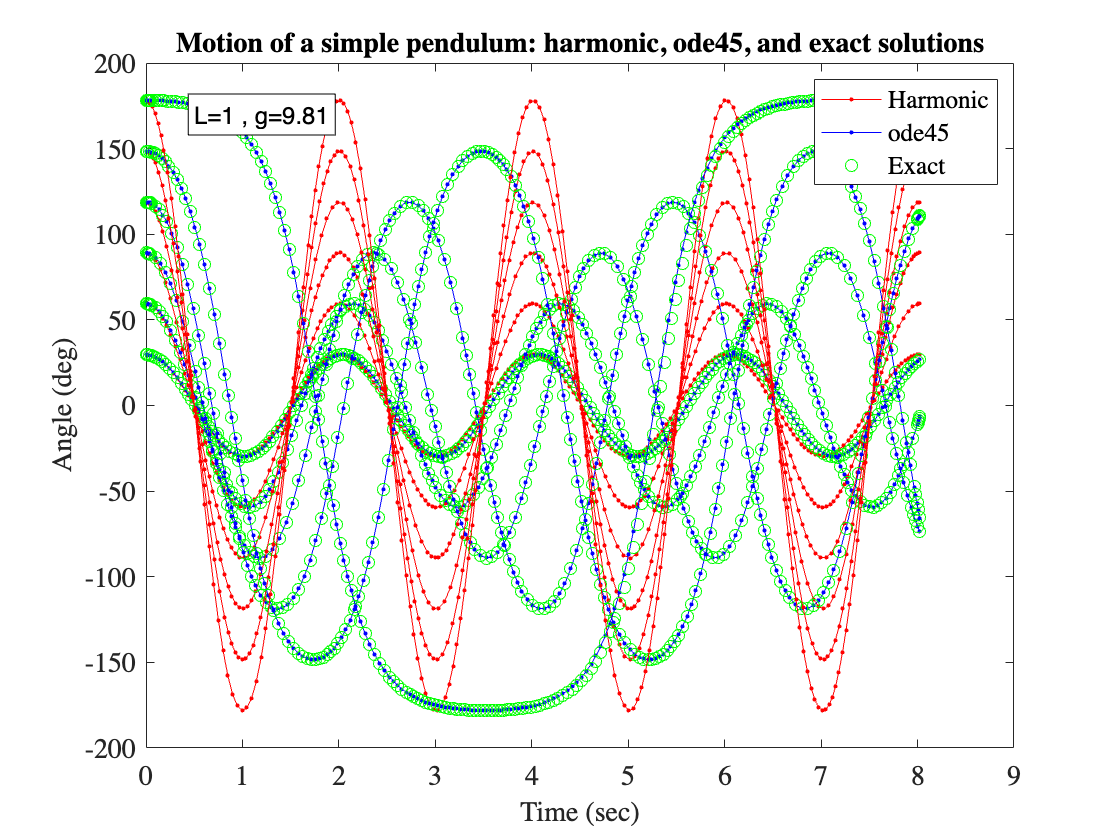

xlabel('Time (sec)','FontSize',14)
ylabel('Angle (deg)','FontSize',14)
title('Motion of a simple pendulum: harmonic, ode45, and exact solutions','FontSize',14)

Note that energy conservation requires the maximum amplitude to repeat. The period of the exact solution increases with amplitude. Large amplitude motions are quite anharmonic. 

Plot period as a function of angle.

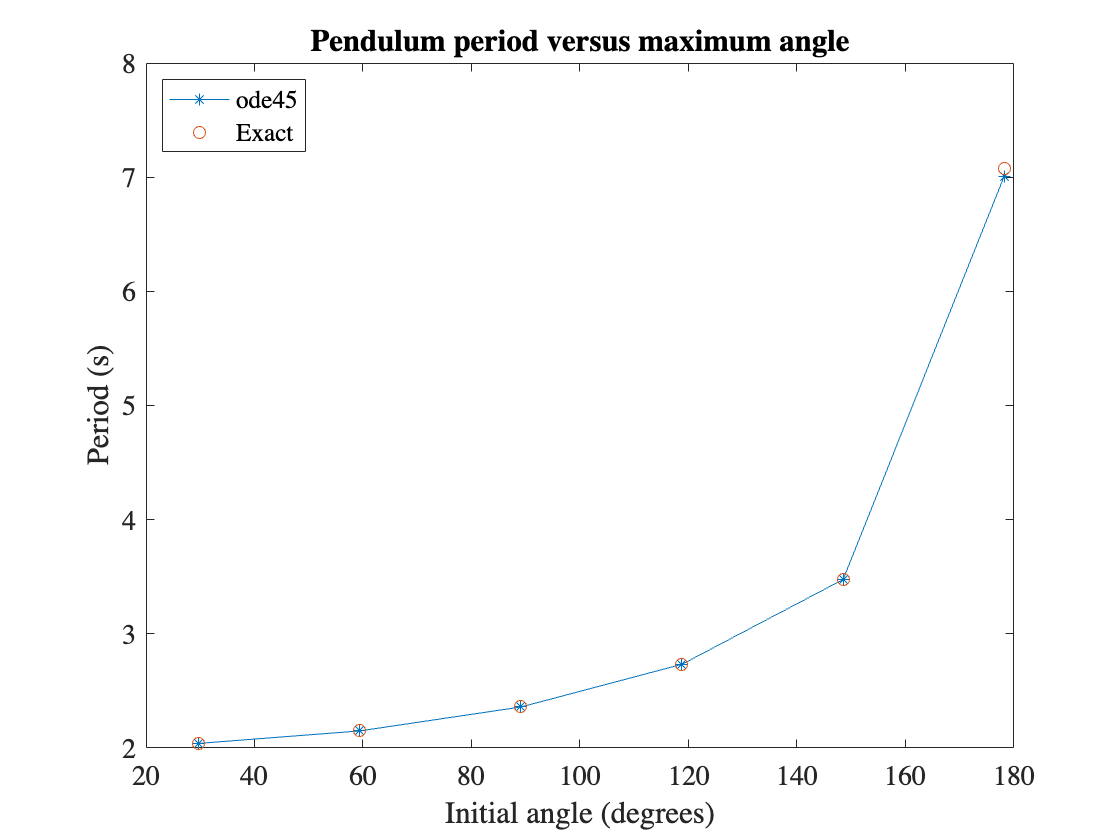

figure
plot(rad2deg(theta0_ode45),period_ode45,'*-','DisplayName','ode45')
hold on
m=(sin(theta0_ode45/2)).^2;
Texact=T0*2*ellipke(m)/pi;
plot(rad2deg(theta0_ode45),Texact,'o','DisplayName','Exact')
hold off
xlabel('Initial angle (degrees)');ylabel('Period (s)')
legend('Location','NW')
title('Pendulum period versus maximum angle')

## Compare the power spectra of the harmonic and ode45 data.

### Try this: Change the maximum time to 1000 periods to improve the frequency resolution in the power spectrum.

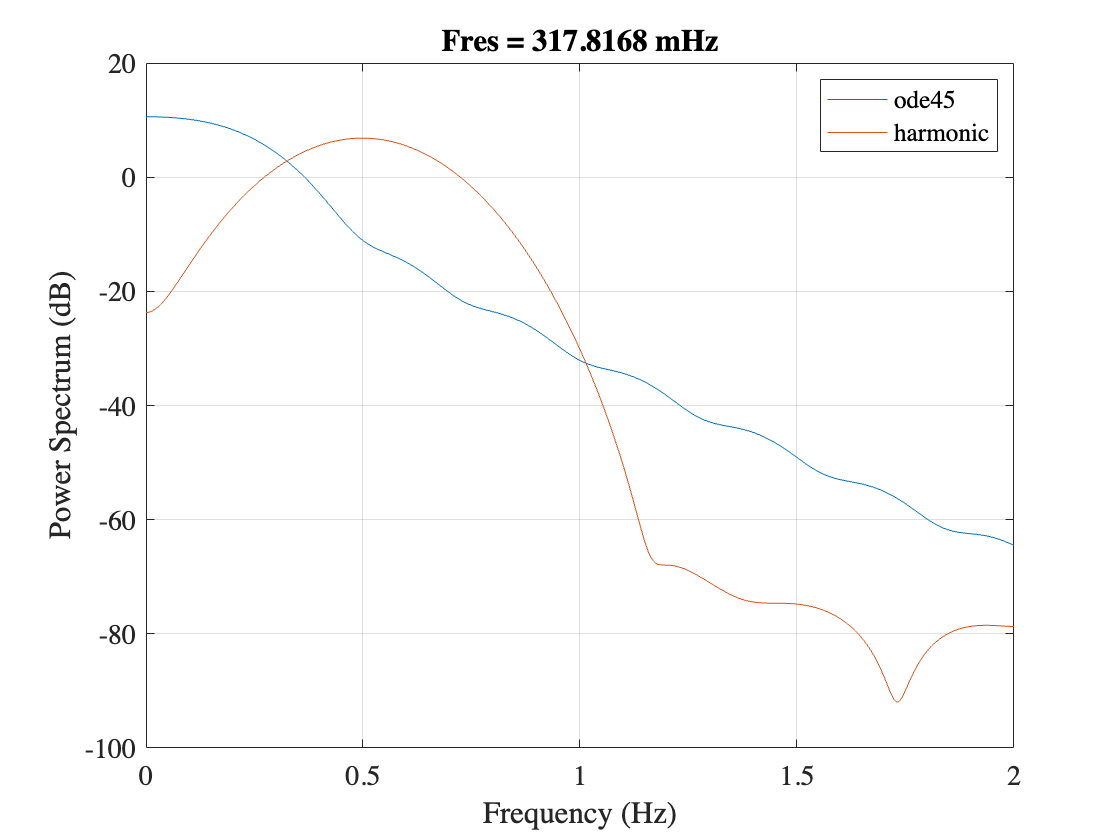

figure
pspectrum(theta_ode45,t_ode45)
hold on
pspectrum(theta_harmonic,t_ode45)
xlim([0,2])
legend("ode45","harmonic")

## Calculate period versus amplitude (maximum angle) to simulate measurements of period vs amplitude.

L=1;% length in m
g=9.81;% acceleration of gravity
T0=2*pi*sqrt(L/g);% simple pendulum period in SHO approximation
N=100; % number of initial angles
thmax=90;% max angle in degrees
dth=thmax/N;% angle increment
th=[0:dth:thmax];% initial angles in degrees
m=sin(th*2*pi/360/2).^2 ;% parameter needed at each angle

Calculate period versus angle in a nonlinear approximation and the exact result expressed in terms of elliptic integrals.  The nonlinear approximation can be derived from the exact solution or by perturbation theory in which the Taylor series for $\sin\theta$ is used and the SHO first approximation solution is substituted into the nonlinear (cubic) term which is then a known function that is formally equivalent to a harmonic driving force. That topic is covered in an intermediate level mechanics class.

Compute period using a nonlinear approximate formula. Note this will fail at large angles and result in imaginary values.

Tnonlin=T0./sqrt(1-(th*2*pi/360).^2/8);

Compute exact result for the period.

Texact=T0*2*ellipke(m)/pi;  %full solution for the period versus amplitude
figure
plot(th,Tnonlin,'b.',th, Texact,'k-')

Overlay the simple harmonic oscillator period.

line([0,thmax],[T0,T0],'color','red'); 
%axis([0 thmax 0.95 1.2]);
h=legend('T nonlin. approx','T exact','T simple harmonic');
set(h,'FontSize',14)
xlabel('Amplitude (degrees)','FontSize',14)
ylabel('Period (s)','FontSize', 14)

Restrict plot to below 90 degrees so it is applicable to a simple pendulum composed of a mass suspended by a string of negligible mass.

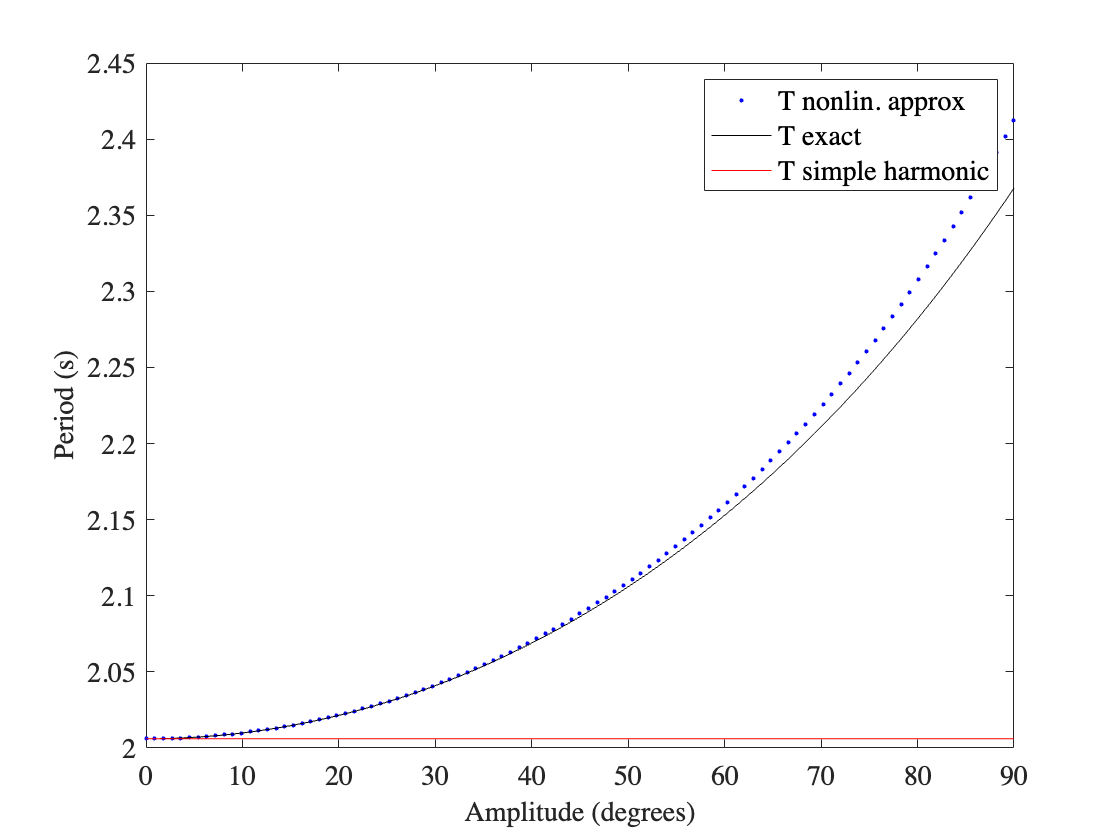

xlim([0,90])

The exact period deviates from the harmonic period by as much as 17% and from the nonlinear approximation by as much as 2%. 

## Make an illustrative nonlinear fit to simulated measurements of period versus angle.

Use exact values for period versus angle and add normally distributed noise  to each period to simulate a real data sample.

Pick a constant standard deviation for time noise in seconds.

timeerror=.001;

Get a vector of random numbers distributed normally with mean 0 and $\sigma$=timeerror and add it to the exact periods.

Terror = normrnd(0,timeerror,1,length(Texact)); % period errors
Tsmear = Texact+Terror; % smeared periods

Make some vectors of the (constant) standard deviations for plotting error bars. The error bars show in general 1 std up and 1 std down as an indication of the range we would expect to find a point were the actual point at the mean of the distribution for that point.

TError = timeerror*ones(1,length(Texact));% errorbar half-lengths
thError= ones(1,length(th)); % angular error in degrees

Plot the data with error bars, both vertical ones and horizontal ones.

figure
errorbar(th,Tsmear,-TError,TError,-thError,thError)
xlabel('Amplitude (degrees)');ylabel('Period (s)');
title('Simulated pendulum period versus release angle');

Fit the period versus angle to the nonlinear approximation model. $T = T_0/\sqrt(1-\theta^2/8)$

Caveat: The following fit takes into account period uncertainties, ignoring significant angular uncertainties which in practice might be of order 1 degree.

x=th; % x axis is angle
y= Tsmear; % y-axis is time

Define the model function to fit to the data as the approximate expression for period versus angle.

modelfunc = @(b,x)(b(1)./sqrt(1-(x*pi/180).^2/8));

### Try this: Define the model function to fit to the data as the exact expression for period versus angle.

%modelfunc = @(b,x)(b(1).*(2/pi).*ellipke( (sin(deg2rad(x)./2)).^2) );

Use a weighted fit, each point weighted with inverse variance 1/$\sigma^2$.

weights = 1./TError.^2; 

We must supply initial estimates for the parameters beta to be handed to the function `nlinfit`. We are only going to fit for one parameter, the overall scale, so the nonlinear fit is entirely unnecessary but illustrates what to do.

beta0=T0;

We hand `nlinfit` the x and y values, the name of the model function, and weights. It makes calls to the function using the parameters called `b` in the model function with the values x to predict the values y, wiggles b around to minimize the weighted sum of squared deviations (vertical only), until it meet some default criterion, then returns the fitted parameter values we capture as `beta`, a covariance matrix we capture as `CovB` containing the errors on the parameters, and some other matrices R (residuals) and J (jacobian).

[beta, R,J,CovB,MSE,ErrorModelInfo]=nlinfit(x,y,modelfunc,beta0,'Weights',weights);

Print parameter estimates and their standard errors. 

Note: CovB is, for a muti-parameter fit, a covariance matrix with standard variances of the parameters on the diagonal so we use the matrix form of the command for extracting the standard parameter errors from the diagonal elements to illustrate what to do when you have many parameters.

beta,sqrt(diag(CovB))

beta =        1.9983


ans =     0.0010429


Calculate fit values at the values x using the model function and fit parameter estimates.

Tfit=modelfunc(beta,x);

Superpose fit results on the plot of the simulated data.

hold on
plot(th,Tfit,'*-')

In the next command, because we are including a location name-value pair of strings, we group the strings 'data' and 'fit to so `legend` can associate these strings with the plotted content.

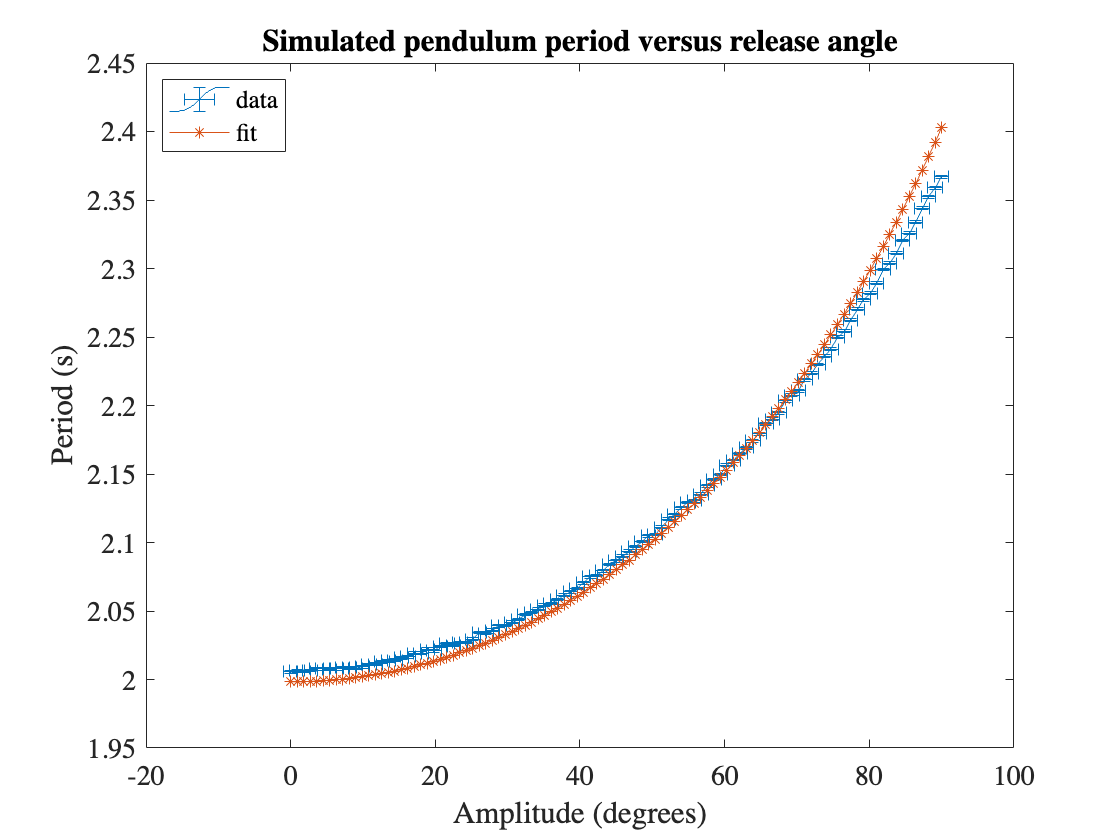

legend({'data','fit'},'Location','northwest');

Compute the chisq per point for the fit from the weighted residuals. This should be rough unity for a good fit.

chisq=sum((R.^2))/(length(R)-length(beta))

chisq =        123.96


Notice our 1-parameter fit moves the model curve up and down to minimize the sum of squared residuals and is low for small amplitude and high for high amplitude when fitting the approximate expression for period versus amplitude. The average  $\chi^2$ per degree of freedom (data point) is much larger than unity. We are trying to fit a model to the curve which simply doesn't fit when we include the high angular amplitude data. 

### Try this: Does using the exact model produce a reasonable chi-square value indicating a good fit?

license('inuse')

matlab
signal_toolbox
statistics_toolbox
symbolic_toolbox


version

ans = '9.13.0.2080170 (R2022b) Update 1'

function derivs = pendulum_derivs( t, y,w0)

Returns the derivatives for the pendulum ode solution

t= time,parm(1)=angle, parm(2)=angular velocity, w0=natural frequency

derivs = [ y(2); -w0^2*sin(y(1))];

### Try this: Change the function to have ode45 integrate the harmonic approximation.

%derivs = [ y(2); -w0^2*y(1)];
end

Event function for ode45 to return zeros.

function [position,isterminal,direction] = amplitudezero(t,y, omega0)
  position = y(1); % The value that we want to be zero
  isterminal = 0;  % 0=do not halt integration 
  direction = 0;   % The zero can be approached from either direction
end

## **References**

1) Alvaro H. Salas, Jairo E. Castillo H. [Exact solution to Duffing equation and the pendulum equation](http://www.m-hikari.com/ams/ams-2014/ams-173-176-2014/salasAMS173-176-2014.pdf), Applied Mathematical Sciences, Vol. 8, 2014, no. 176, 8781-8789 [http://dx.doi.org/10.12988/ams.2014.44243](http://dx.doi.org/10.12988/ams.2014.44243)